%This file is used to do all experiment related plots and computations used
%in the thesis

load("SCORES1.mat");
load("scores_noise.mat");

scores(:,:,:,1) = scores(:,:,:,1)*100;

disp(size(scores));

    50    41    16     5





% Define metric names for clarity
metricNames = {'Accuracy','Sensitivity', 'Specificity', 'Precision', 'F1-Score'};
thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
beta_values =   [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125,4.25,4.375,4.5,4.625,4.75,4.875,5];
rng_list = (1:10);

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores,2),size(scores, 3), length(metricNames));
metricsStds = zeros(size(scores, 2), size(scores, 3), length(metricNames)); % For standard deviations

% Loop over beta values
for j = 1 : size(scores,2)
    for i = 1:size(scores, 3)
        % Compute mean and standard deviation across seeds (dimension 1)
        means = squeeze(mean(scores(1:10,j, i, :), 1)); % 1 x 4 vector
        stds = squeeze(std(scores(1:10,j, i, :), [], 1)); % 1 x 4 vector
        
        % Store means and display results
        metricsMeans(j, i, :) = means;
        metricsStds(j, i, :) = stds;

    end
end



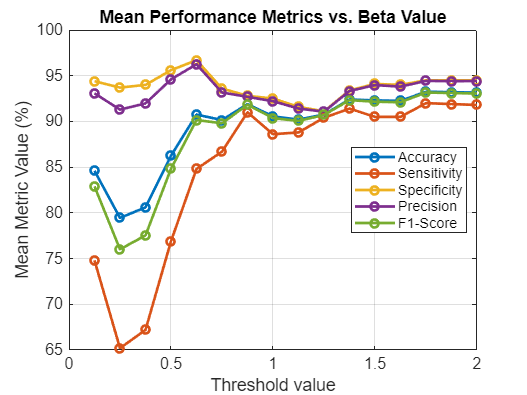

% Plot mean metrics vs. beta values
figure;
plot(thresholds, squeeze(metricsMeans(16,:,:)), '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Threshold value');
ylabel('Mean Metric Value (%)');
title('Mean Performance Metrics vs. Beta Value');
legend(metricNames, 'Location', 'best');
grid on;
set(gca, 'FontSize', 12);

maxThresholds = zeros(length(beta_values),1);
maxThresholdsIdx = zeros(length(beta_values),1);
stdAtMaxThresholds = zeros(length(beta_values), 1);

for i = 1:length(beta_values)
    results = squeeze(metricsMeans(i, :, 5)); % F1-score means
    stds = squeeze(metricsStds(i, :, 5)); % F1-score standard deviations
    [maxValue, idx] = max(results);
    maxThresholdsIdx(i) = idx;
    maxThresholds(i) = maxValue;
    stdAtMaxThresholds(i) = stds(idx); % Standard deviation at the optimal threshold
end

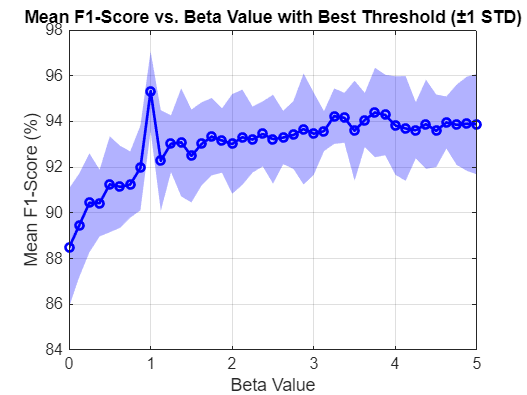

% Plot mean F1-score vs. beta values with shaded area (±1 std)
figure;
% Define the x-axis for the shaded area (forward and backward for fill)
x = [beta_values, fliplr(beta_values)];
% Define the y-axis for the shaded area (mean ± std)
y = [maxThresholds' + stdAtMaxThresholds', fliplr(maxThresholds' - stdAtMaxThresholds')];
% Create shaded area
fill(x, y, 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
% Plot the mean line
plot(beta_values, maxThresholds, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
xlabel('Beta Value');
ylabel('Mean F1-Score (%)');
title('Mean F1-Score vs. Beta Value with Best Threshold (±1 STD)');
grid on;
set(gca, 'FontSize', 12);
hold off;

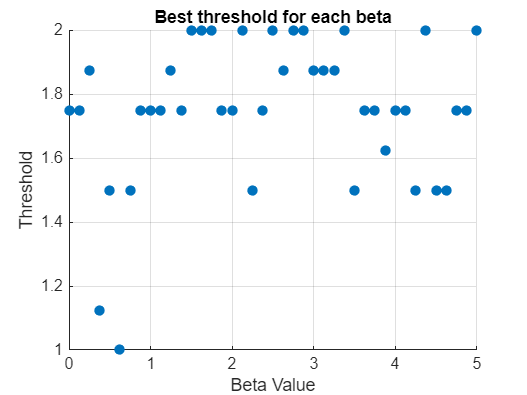

% Plot mean metrics vs. beta values as a scatter plot
figure;
scatter(beta_values, squeeze(thresholds(maxThresholdsIdx)), 60, 'filled');
xlabel('Beta Value');
ylabel('Threshold');
title('Best threshold for each beta');
grid on;
set(gca, 'FontSize', 12);

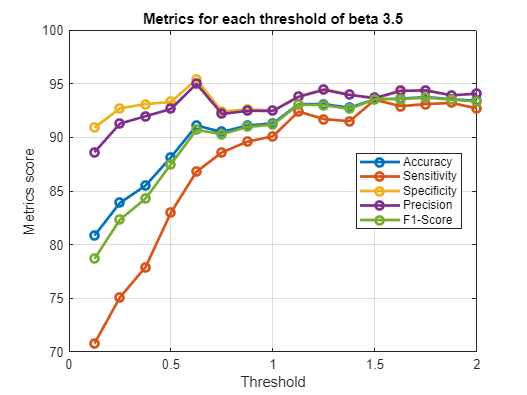



% Define metric names for clarity

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores, 3), length(metricNames));

means = zeros();
% Loop over beta values
for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1)
    means = squeeze(mean(scores(1:10,34, i, :), 1)); % 1 x 4 vector
    stds = squeeze(std(scores(1:10,34, i, :), [], 1)); % 1 x 4 vector
    
    % Store means and display results
    metricsMeans(i, :) = means;

end

% Plot mean metrics vs. beta values
figure;
plot(thresholds, metricsMeans, '-o', 'LineWidth', 2, 'MarkerSize', 6);
xlabel('Threshold');
ylabel('Metrics score');
title('Metrics for each threshold of beta 3.5');
legend(metricNames, 'Location', 'best');
grid on;

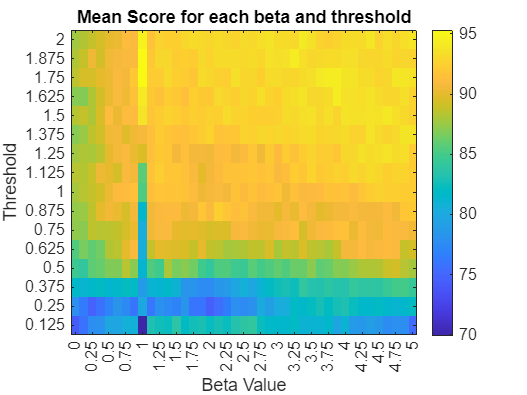

metricsMeans = zeros(size(scores, 3), size(scores,2));

for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1)
    means = squeeze(mean(scores(1:10,:, i, 5), 1)); % 1 x 4 vector
    stds = squeeze(std(scores(1:10,:, i, 5), [], 1)); % 1 x 4 vector
    
    % Store means and display results
    metricsMeans(i, :) = means;

end

% Plot heatmap
figure;
imagesc(metricsMeans);
colorbar;

% Fix y-axis direction
set(gca, 'YDir', 'normal');

% Axis labels and title
xlabel('Beta Value');
ylabel('Threshold');
title('Mean Score for each beta and threshold');
set(gca, 'FontSize', 12);
set(colorbar, 'FontSize', 12); % Optional: consistent font size

% Set ticks and labels
skip = 2;
xticks(1:skip:length(beta_values));
xticklabels(string(beta_values(1:skip:end)));
yticks(1:length(thresholds));
yticklabels(string(thresholds));

beta_values =   [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125,4.25,4.375,4.5,4.625,4.75,4.875,5];
thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];

% Define metric names for clarity
metricNames = {'Accuracy','Sensitivity', 'Specificity', 'Precision', 'F1-Score'};

% Preallocate matrix for mean metrics
metricsMeans2 = zeros(size(scores,2),size(scores, 3), length(metricNames));

% Loop over beta values
for j = 1 : size(scores,2)
    for i = 1:size(scores, 3)
        % Compute mean and standard deviation across seeds (dimension 1)
        means = squeeze(mean(scores(1:10,j, i, :), 1)); % 1 x 4 vector
        stds = squeeze(std(scores(1:10,j, i, :), [], 1)); % 1 x 4 vector
        
        % Store means and display results
        metricsMeans2(j, i, :) = means;
        
    end
end

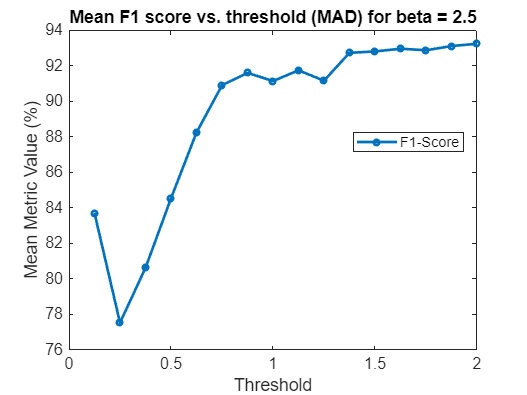

% Plot mean metrics vs. beta values
figure;
plot(thresholds, squeeze(metricsMeans2(21,:,5)), '-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Threshold');
ylabel('Mean Metric Value (%)');
title('Mean F1 score vs. threshold (MAD) for beta = 2.5');
legend(metricNames(5), 'Location', 'best');
set(gca, 'FontSize', 12);

maxThresholds2 = zeros(length(beta_values),1);
maxThresholdsIdx2 = zeros(length(beta_values),1);
for i = 1 : length(beta_values)
    results = squeeze(metricsMeans2(i,:,5));
    [maxValue, idx] = max(results);
    maxThresholdsIdx2(i) = idx;
    maxThresholds2(i) = maxValue;
end

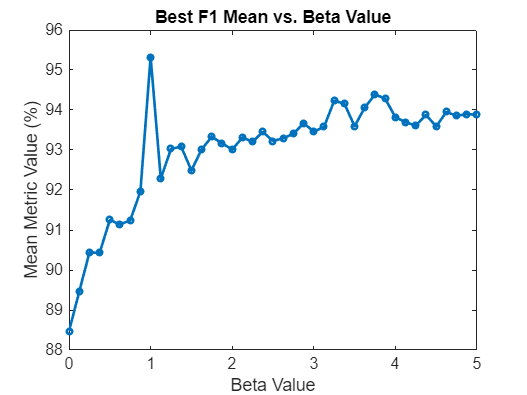

% Plot mean metrics vs. beta values
figure;
plot(beta_values, squeeze(maxThresholds2), '-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Beta Value');
ylabel('Mean Metric Value (%)');
title('Best F1 Mean vs. Beta Value');
set(gca, 'FontSize', 12);

% Plot mean metrics vs. beta values
for i = 1 : length(maxThresholdsIdx2)
    threshold_work2(i) = thresholds(maxThresholdsIdx2(i));
end

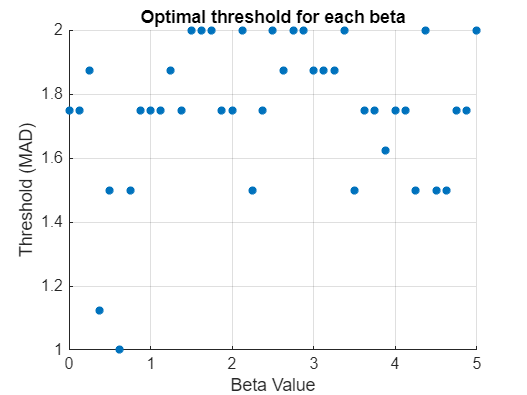


figure;
scatter(beta_values, squeeze(threshold_work2),'*', 'LineWidth', 2 );
xlabel('Beta Value');
ylabel('Threshold (MAD)');
title('Optimal threshold for each beta');
grid on;
set(gca, 'FontSize', 12);

scores_noise(:,:,:,:,1) = scores_noise(:,:,:,:,1)*100;

disp(size(scores_noise));

    10    41     8     4     5





% Define metric names for clarity
metricNames = {'Accuracy','Sensitivity', 'Specificity', 'Precision', 'F1-Score'};

% Preallocate matrix for mean metrics
metricsMeans = zeros(size(scores_noise,2),size(scores_noise, 3),size(scores_noise,4)+1, length(metricNames));
metricsMeans(:, :, 1, :) = metricsMeans2(:,end-size(scores_noise, 3)+1:end, :);
% Loop over beta values
for j = 1 : size(scores_noise,2)
    for i = 1:size(scores_noise, 3)
        for k = 1: size(scores_noise,4)
            % Compute mean and standard deviation across seeds (dimension 1)
            means = squeeze(mean(scores_noise(1:10,j, i,k, :), 1)); % 1 x 4 vector
            stds = squeeze(std(scores_noise(1:10,j, i,k, :), [], 1)); % 1 x 4 vector
            
            % Store means and display results
            metricsMeans(j, i, k+1, :) = means;
 
        end
    end
end



size(metricsMeans)

ans =     41     8     5     5


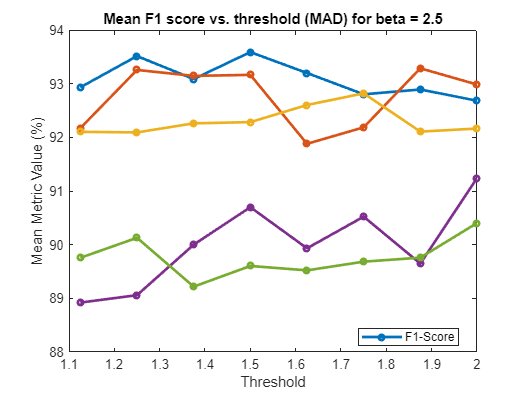

% Plot mean metrics vs. beta values
thresholds = [1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];

figure(1);
plot(thresholds, squeeze(metricsMeans(37,:,:,5)), '-o', 'LineWidth', 2, 'MarkerSize', 4);
xlabel('Threshold');
ylabel('Mean Metric Value (%)');
title('Mean F1 score vs. threshold (MAD) for beta = 2.5');
legend(metricNames(5), 'Location', 'best');

maxThresholds = zeros(size(metricsMeans,1),size(metricsMeans,3));
maxThresholdsIdx = zeros(size(metricsMeans,1),size(metricsMeans,3));
for i = 1 : size(metricsMeans,1)
    for j = 1 : size(metricsMeans,3)
        results = squeeze(metricsMeans(i,:,j,5));
        [maxValue, idx] = max(results);
        maxThresholdsIdx(i,j) = idx;
        maxThresholds(i,j) = maxValue;
    end
end

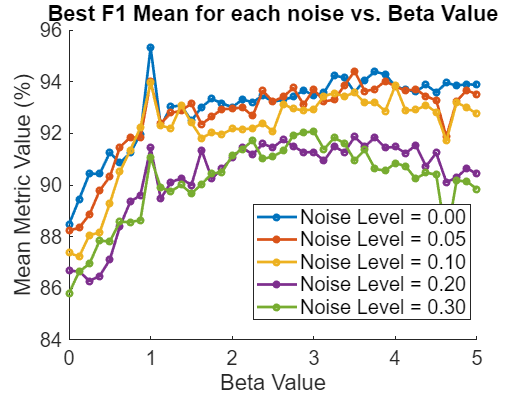

noise_levels = [0.05, 0.1, 0.2, 0.3];

plotRange = [0, noise_levels];

figure;
hold on;

plot(beta_values, squeeze(maxThresholds), '-o', 'LineWidth', 2, 'MarkerSize', 4);

hold off;
xlabel('Beta Value', 'FontSize', 1.5 * get(groot, 'defaultAxesFontSize'));
ylabel('Mean Metric Value (%)', 'FontSize', 1.5 * get(groot, 'defaultAxesFontSize'));
title('Best F1 Mean for each noise vs. Beta Value', 'FontSize', 1.5 * get(groot, 'defaultAxesFontSize'));

legendStrings = arrayfun(@(x) sprintf('Noise Level = %.2f', x), plotRange, 'UniformOutput', false);
legend(legendStrings, 'Location', 'best', 'FontSize', 1.5 * get(groot, 'defaultAxesFontSize'));

set(gca, 'FontSize', 1.5 * get(groot, 'defaultAxesFontSize'));  % Axis tick labels

% Plot mean metrics vs. beta values
for i = 1 : length(maxThresholdsIdx)
    threshold_work(i) = thresholds(maxThresholdsIdx(i));
end

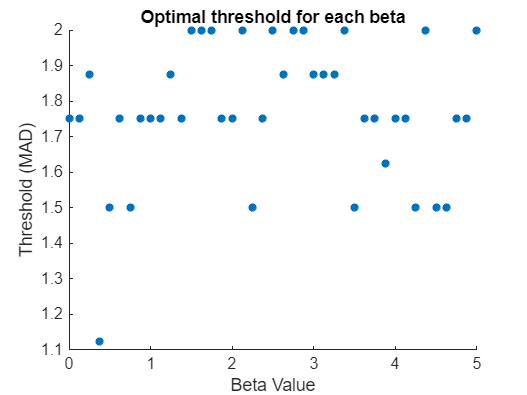

figure;
scatter(beta_values, squeeze(threshold_work),'*', 'LineWidth', 2 );
xlabel('Beta Value');
ylabel('Threshold (MAD)');
title('Optimal threshold for each beta');
set(gca, 'FontSize', 12);

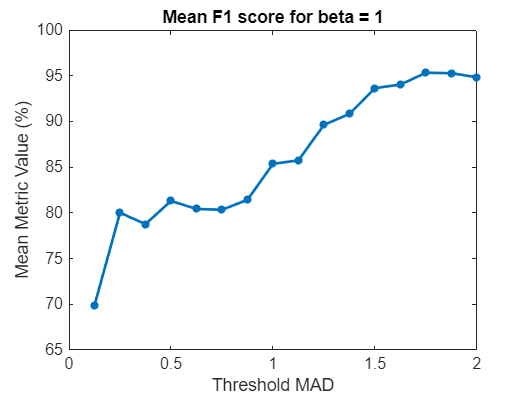



% Define metric names for clarity

% Preallocate matrix for mean metrics
metricNames = {'Accuracy', 'Sensitivity', 'Specificity', 'Precision', 'F1-Score'};
thresholds = [0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2];
% Assuming beta_values is defined as in the previous context
beta_values = [0, 0.125, 0.25, 0.375, 0.5, 0.625, 0.75, 0.875, 1, 1.125, 1.25, 1.375, 1.5, 1.625, 1.75, 1.875, 2, 2.125, 2.25, 2.375, 2.5, 2.625, 2.75, 2.875, 3, 3.125, 3.25, 3.375, 3.5, 3.625, 3.75, 3.875, 4, 4.125, 4.25, 4.375, 4.5, 4.625, 4.75, 4.875, 5];

% Preallocate matrix for mean and standard deviation
metricsMeans = zeros(size(scores, 3), length(metricNames));
metricsStds = zeros(size(scores, 3), length(metricNames)); % For standard deviations

% Loop over thresholds (dimension 3)
for i = 1:size(scores, 3)
    % Compute mean and standard deviation across seeds (dimension 1) for F1-score at beta index 9
    means = squeeze(mean(scores(1:10, 9, i, 5), 1)); % Scalar mean for F1-score
    stds = squeeze(std(scores(1:10, 9, i, 5), [], 1)); % Scalar std for F1-score
    
    % Store means and standard deviations
    metricsMeans(i, 5) = means; % Store in F1-score column
    metricsStds(i, 5) = stds; % Store in F1-score column
end

% Plot mean metrics vs. beta values
figure;
plot(thresholds, metricsMeans(:,5), '-*', 'LineWidth', 2);
xlabel('Threshold MAD');
ylabel('Mean Metric Value (%)');
title('Mean F1 score for beta = 1');
set(gca, 'FontSize', 12);

for i = 1 : 4
    for j = 1 : length(beta_values)
        delta(i,j) = maxThresholds(j,i+1)-maxThresholds(j,1);
    end
end

for j = 1 : length(beta_values)
    mean_delta(j) = mean(delta(:,j));
    mean_noise(j) = mean(maxThresholds(j,2:end));
end

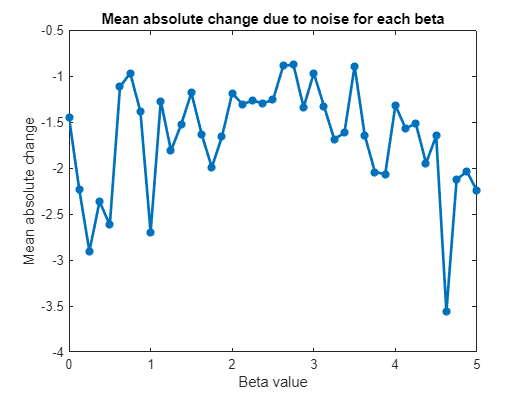

figure;
plot(beta_values, mean_delta, '-*', 'LineWidth', 2);
xlabel('Beta value');
ylabel('Mean absolute change');
title('Mean absolute change due to noise for each beta');

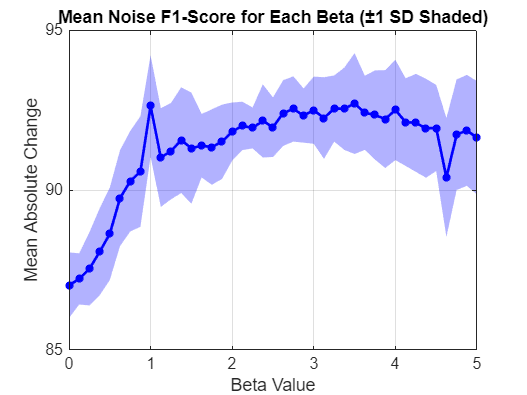

% Compute standard deviation for mean_noise
std_noise = zeros(1, length(beta_values));
for j = 1:length(beta_values)
    std_noise(j) = std(maxThresholds(j, 2:end), [], 2); % Standard deviation across noise levels
end

% Plot mean_noise vs. beta_values with shaded area (±1 std)
figure;
% Define the x-axis for the shaded area (forward and backward for fill)
x = [beta_values, fliplr(beta_values)];
% Define the y-axis for the shaded area (mean ± std)
y = [mean_noise + std_noise, fliplr(mean_noise - std_noise)];
% Create shaded area
fill(x, y, 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
hold on;
% Plot the mean line
plot(beta_values, mean_noise, '-*', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b');
xlabel('Beta Value');
ylabel('Mean Absolute Change');
title('Mean Noise F1-Score for Each Beta (±1 SD Shaded)');
grid on; % Added to match your other plots
set(gca, 'FontSize', 12);
hold off;


z(1,:) = mean_noise;
z(2,:) = maxThresholds(:,1)';

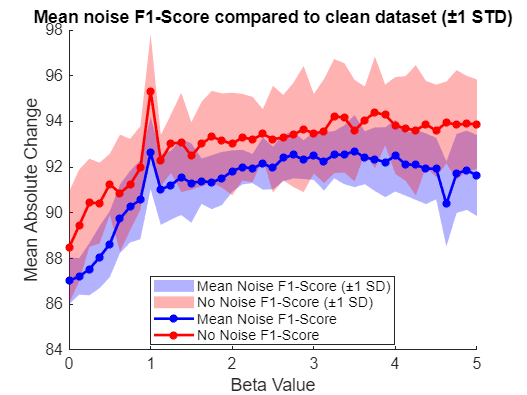

% Compute standard deviations
std_noise = zeros(1, length(beta_values)); % For mean_noise
std_no_noise = zeros(1, length(beta_values)); % For maxThresholds(:,1)

for j = 1:length(beta_values)
    % Standard deviation for mean_noise (across noise levels [0.05, 0.1, 0.2, 0.3])
    std_noise(j) = std(maxThresholds(j, 2:end), [], 2);
    % Standard deviation for no-noise F1-score at optimal threshold
    idx = maxThresholdsIdx(j, 1); % Optimal threshold index for no-noise
    std_no_noise(j) = std(scores(1:10, j, idx, 5), [], 1);
end

% Plot with shaded areas for both mean_noise and no-noise F1-score
figure;
hold on;
% Shaded area for mean_noise
x_shade = [beta_values, fliplr(beta_values)];
y_shade_noise = [z(1,:) + std_noise, fliplr(z(1,:) - std_noise)];
fill(x_shade, y_shade_noise, 'b', 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', 'Mean Noise F1-Score (±1 SD)');
% Shaded area for no-noise F1-score
y_shade_no_noise = [z(2,:) + std_no_noise, fliplr(z(2,:) - std_no_noise)];
fill(x_shade, y_shade_no_noise, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', 'No Noise F1-Score (±1 SD)');
% Plot mean lines
plot(beta_values, z(1,:), '-*', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'b', 'DisplayName', 'Mean Noise F1-Score');
plot(beta_values, z(2,:), '-*', 'LineWidth', 2, 'MarkerSize', 6, 'Color', 'r', 'DisplayName', 'No Noise F1-Score');
hold off;
xlabel('Beta Value');
ylabel('Mean Absolute Change');
title('Mean noise F1-Score compared to clean dataset (±1 STD)');
legend('show', 'Location', 'best');
set(gca, 'FontSize', 12);